close all; clear; clc;

# MEGA 2 blade prop, 10-90% ramps

**Record all** points

**file name**: STv2_1_1_MEGA27d2b_20181205_3.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
diameter = 27 / 12;
radius = diameter/2;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_1_MEGA27d2b_20181205_3.mat');
time3 = STv2_1_1_MEGA27d2b_20181205_3(:,1);                       % [sec]
PWM3 = STv2_1_1_MEGA27d2b_20181205_3(:,2);                        % [micro sec]
Q3 = STv2_1_1_MEGA27d2b_20181205_3(:,4);                          % [ft.lbf]
T3 = STv2_1_1_MEGA27d2b_20181205_3(:,5);                          % [lbf]
Input_V3 = STv2_1_1_MEGA27d2b_20181205_3(:,6);                    % [Volts]
Input_A3 = STv2_1_1_MEGA27d2b_20181205_3(:,7);                    % [Amps]
rot_speed_rpm3 = STv2_1_1_MEGA27d2b_20181205_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3 = rot_speed_rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = STv2_1_1_MEGA27d2b_20181205_3(:,9);                     % [Watts]
P_out_W3 = STv2_1_1_MEGA27d2b_20181205_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff3 = STv2_1_1_MEGA27d2b_20181205_3(:,11);                 % [%]
Prop_Eff3 = STv2_1_1_MEGA27d2b_20181205_3(:,12);                  % [lbf/Watts]
Overall_Eff3 = STv2_1_1_MEGA27d2b_20181205_3(:,13);               % [lbf/Watts]  
ESC_Temp3 = STv2_1_1_MEGA27d2b_20181205_3(:,14);                  % [F]
Motor_Temp3 = STv2_1_1_MEGA27d2b_20181205_3(:,15);                % [F]

disk_loading3 = T3 ./ area;                     % [lb/sq.ft]


Settling_time3 = STv2_1_1_MEGA27d2b_20181205_3(:,17); % [s]
Max_Acc3 = STv2_1_1_MEGA27d2b_20181205_3(:,18);      % [RPM]

throttle3 = (PWM3 - 1000) ./ 10;

## Thrust, Power, and Torque Coefficents

C_T3 = T3 ./ (p .* area * (rot_speed_rad3 * radius).^2);
C_P3 = P_out3 ./ (p .* area .* (rot_speed_rad3 .* radius).^3);
C_Q3 = Q3 ./ (p .* area .* (rot_speed_rad3 .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

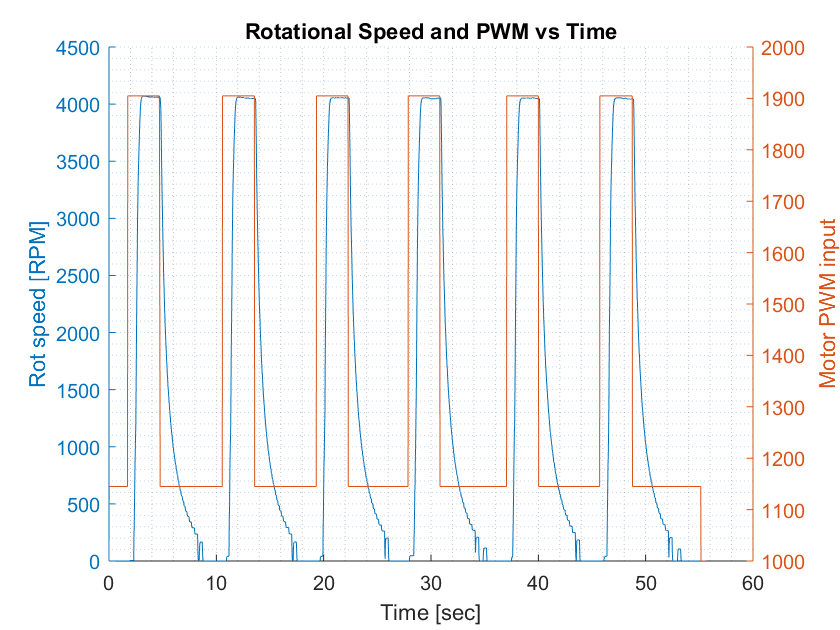



figure(4)
hold on
yyaxis left
plot(time3, rot_speed_rpm3);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time3, PWM3);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

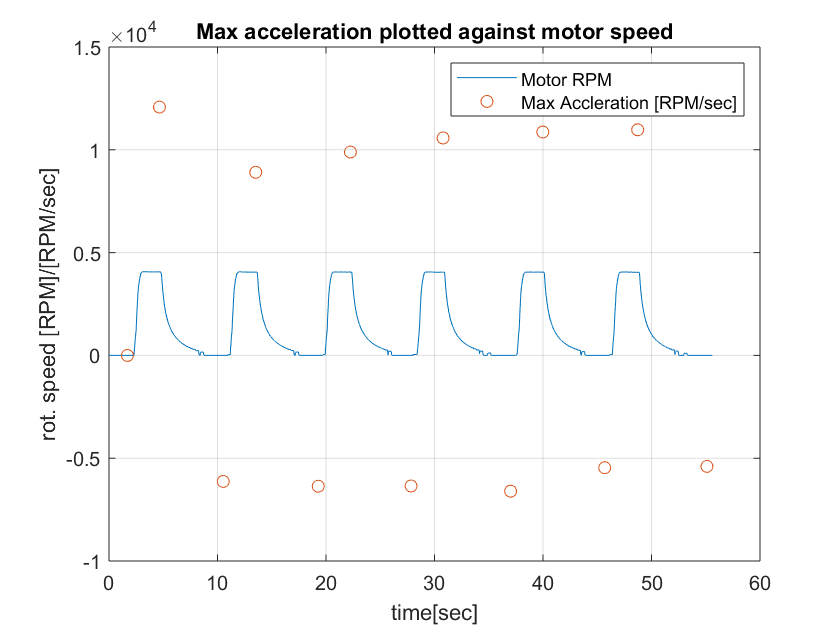



figure(6)
plot(time3, rot_speed_rpm3, time3, Max_Acc3, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]/[RPM/sec]'); 
legend('Motor RPM', 'Max Accleration [RPM/sec]'); grid('on');

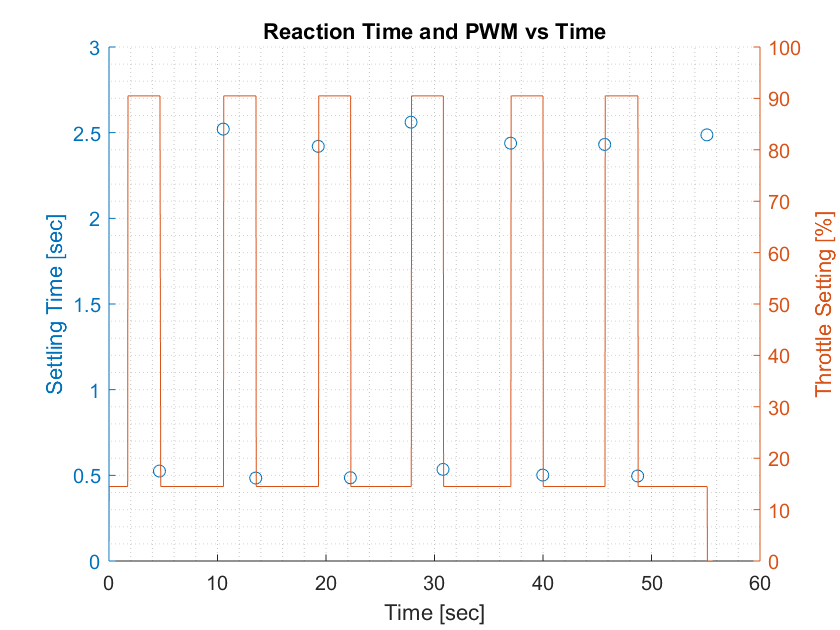


figure(7)
hold on
yyaxis left
plot(time3,Settling_time3, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time3, throttle3);
ylabel('Throttle Setting [%]');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

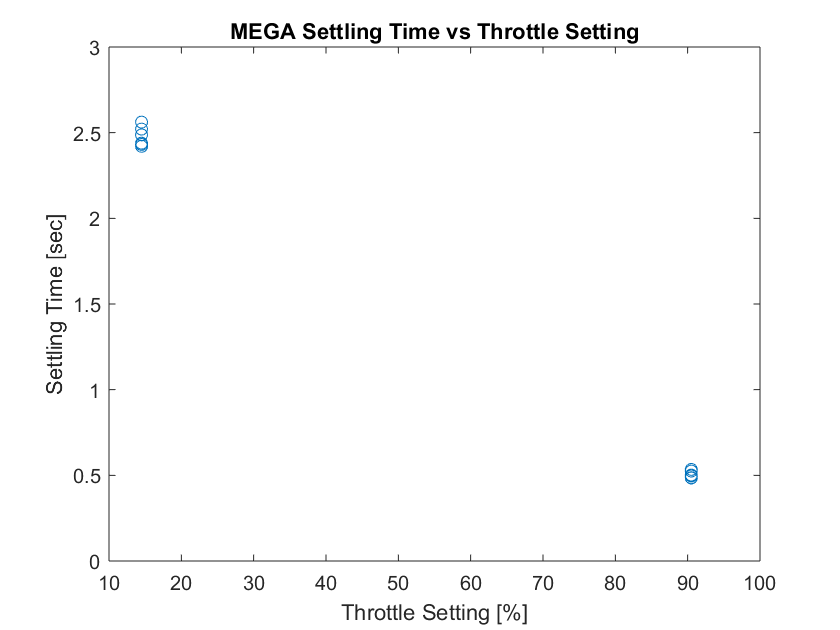


figure(8)
plot(throttle3, Settling_time3, 'o'); title('MEGA Settling Time vs Throttle Setting');
ylabel('Settling Time [sec]'); xlabel('Throttle Setting [%]');